I=imread("cablecar.ppm");
imfinfo("icon.png")

ans = struct with fields:
                  Filename: 'C:\Users\sucho\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\Spatial Math Toolbox\doc\figs\icon.png'
               FileModDate: '28-Oct-2021 08:58:38'
                  FileSize: 56627
                    Format: 'png'
             FormatVersion: []
                     Width: 1067
                    Height: 800
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: 5906
               YResolution: 5906
            ResolutionUnit: 'meter'
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           Sig

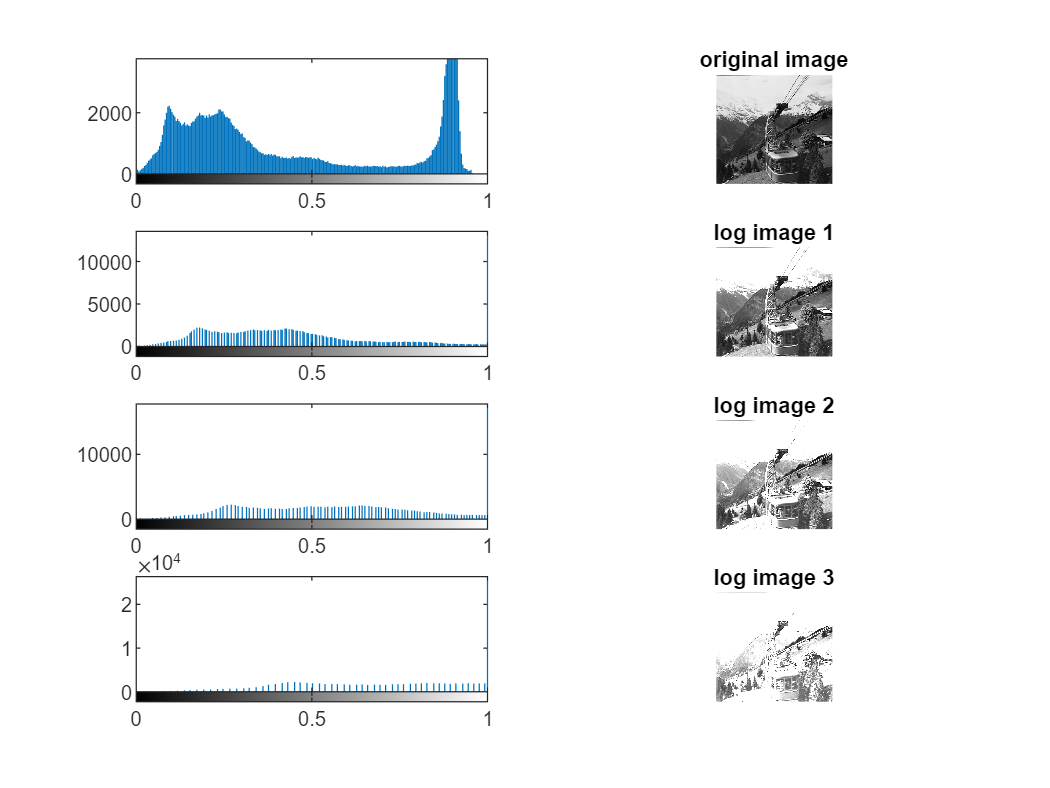

I=rgb2gray(I);
id=im2double(I);

subplot(4,2,1);imhist(id);
subplot(4,2,2);imshow(id);
title('original image');

out1=(2*log(1+id));
out2=(3*log(1+id));
out3=(5*log(1+id));

subplot(4,2,3);imhist(out1);
subplot(4,2,4);imshow(out1);
title('log image 1');

subplot(4,2,5);imhist(out2);
subplot(4,2,6);imshow(out2);
title('log image 2');

subplot(4,2,7);imhist(out3);
subplot(4,2,8);imshow(out3);
title('log image 3');

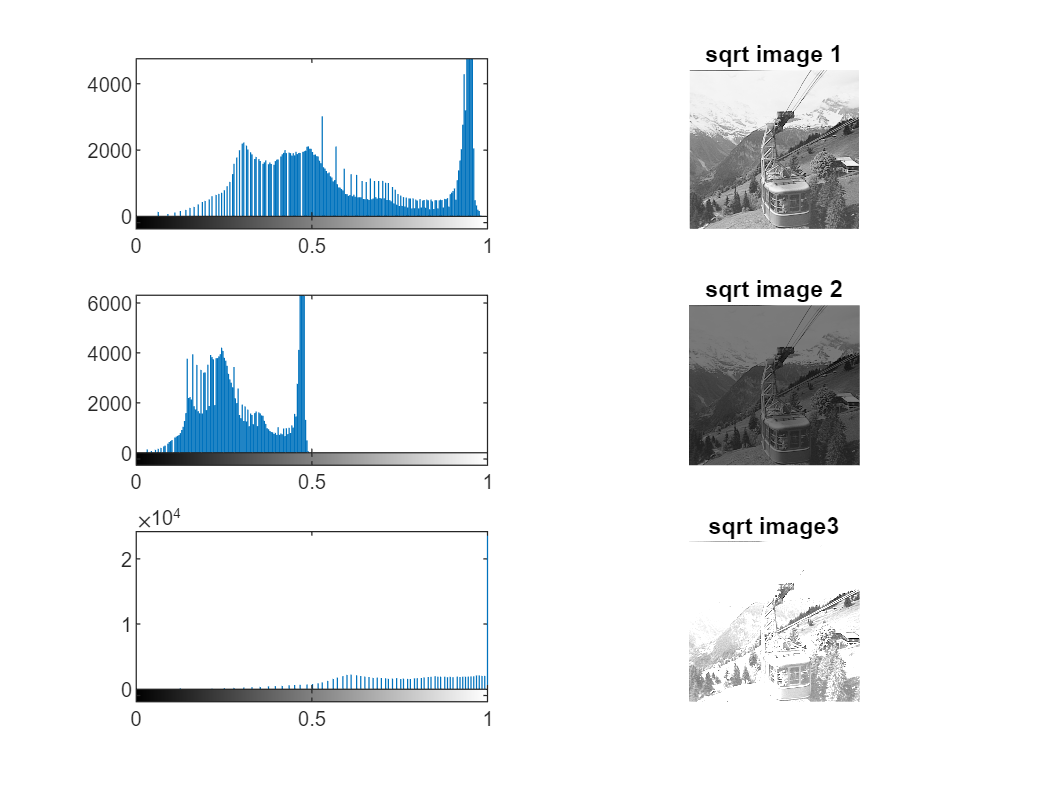


out4=(sqrt(id));
out5=(0.5*sqrt(id));
out6=(2*sqrt(id));

figure

subplot(3,2,1);imhist(out4);
subplot(3,2,2);imshow(out4);
title('sqrt image 1');

subplot(3,2,3);imhist(out5);
subplot(3,2,4);imshow(out5);
title('sqrt image 2');

subplot(3,2,5);imhist(out6);
subplot(3,2,6);imshow(out6);
title('sqrt image3');

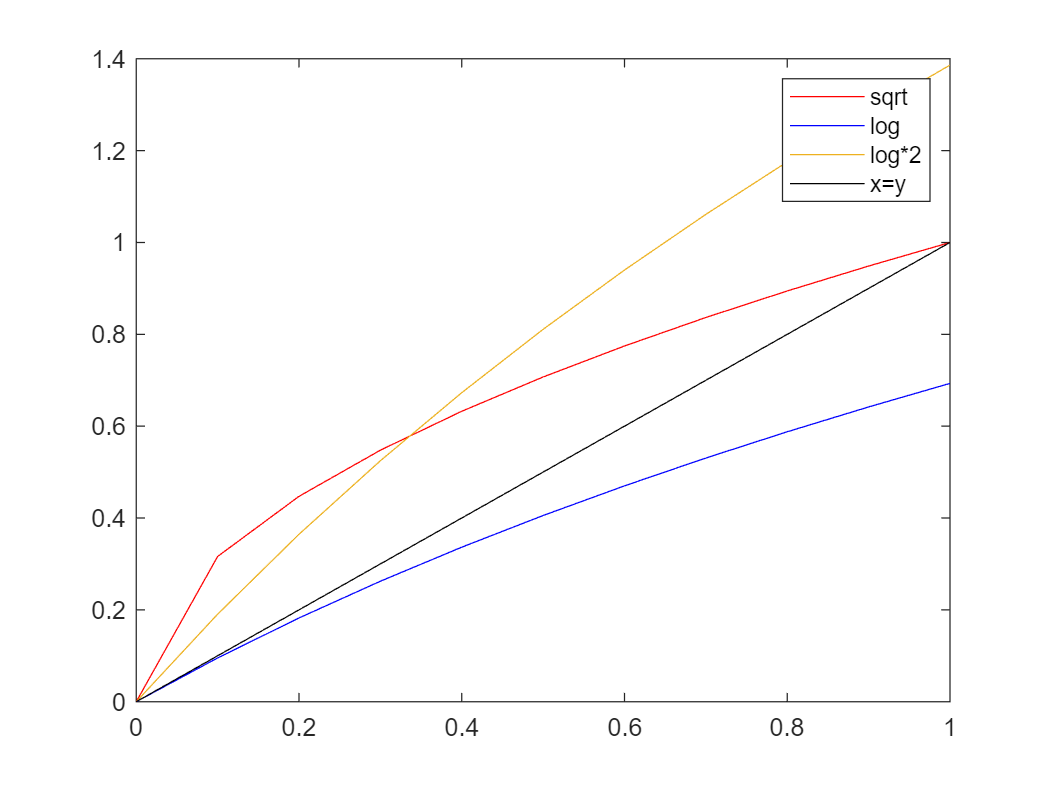

figure
plot(0:0.1:1,sqrt(0:0.1:1),'r');hold on
plot(0:0.1:1,log(1+(0:0.1:1)),'b');
plot(0:0.1:1,(2.*log(1+(0:0.1:1))));
plot(0:0.1:1,0:0.1:1,'k');hold off
legend('sqrt','log','log*2','x=y')

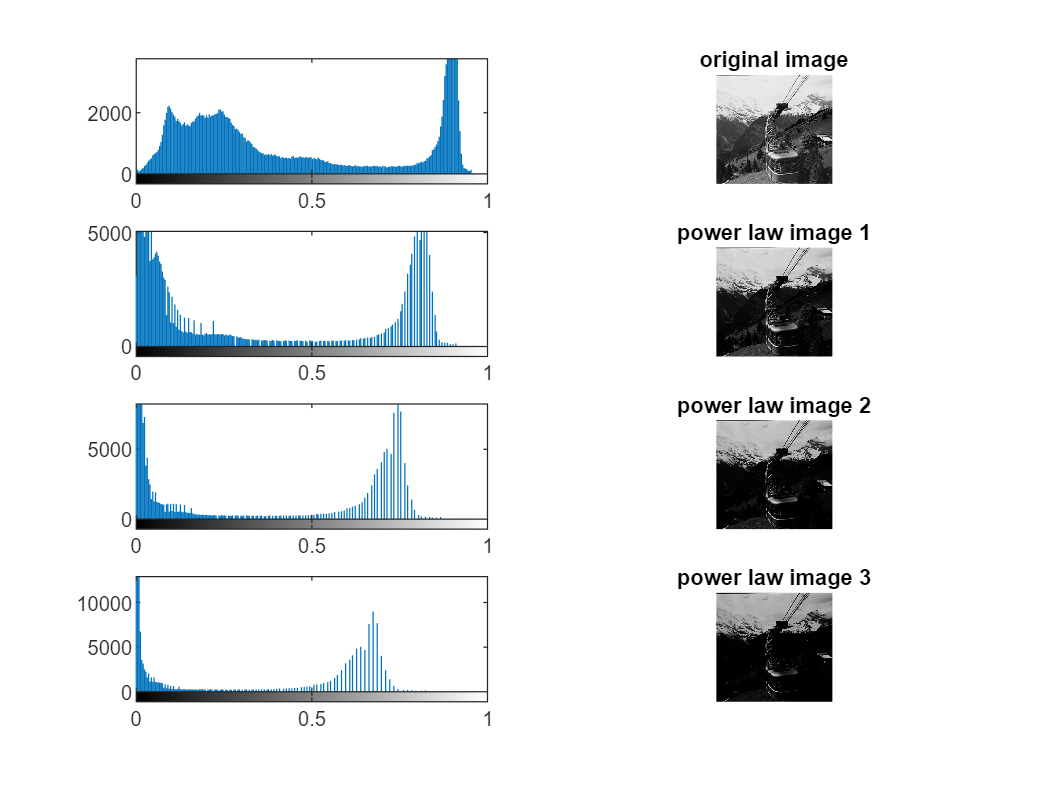

figure

out1=(1*(id.^2));
out2=(1*(id.^3));
out3=(1*(id.^4));

subplot(4,2,1);imhist(id);
subplot(4,2,2);imshow(id);
title('original image');

subplot(4,2,3);imhist(out1);
subplot(4,2,4);imshow(out1);
title('power law image 1');

subplot(4,2,5);imhist(out2);
subplot(4,2,6);imshow(out2);
title('power law image 2');

subplot(4,2,7);imhist(out3);
subplot(4,2,8);imshow(out3);
title('power law image 3');

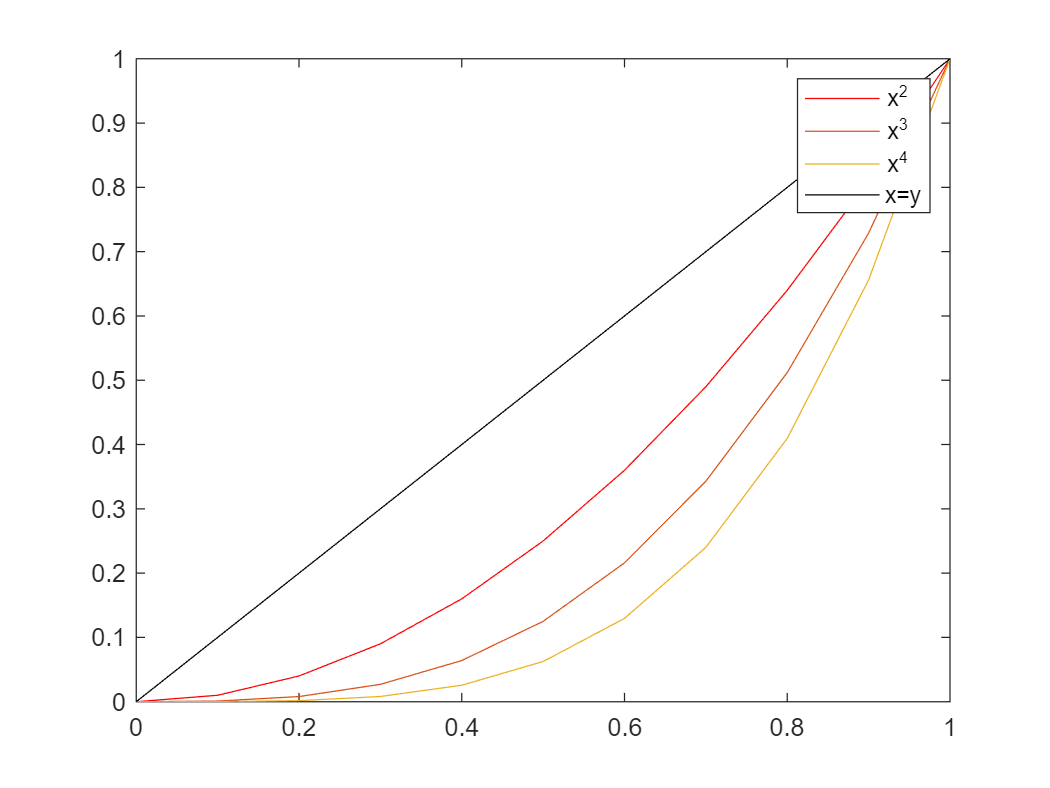


figure
plot(0:0.1:1,(0:0.1:1).^2,'r');hold on
plot(0:0.1:1,(0:0.1:1).^3);
plot(0:0.1:1,(0:0.1:1).^4);
plot(0:0.1:1,0:0.1:1,'k');hold off
legend('x^2','x^3','x^4','x=y')

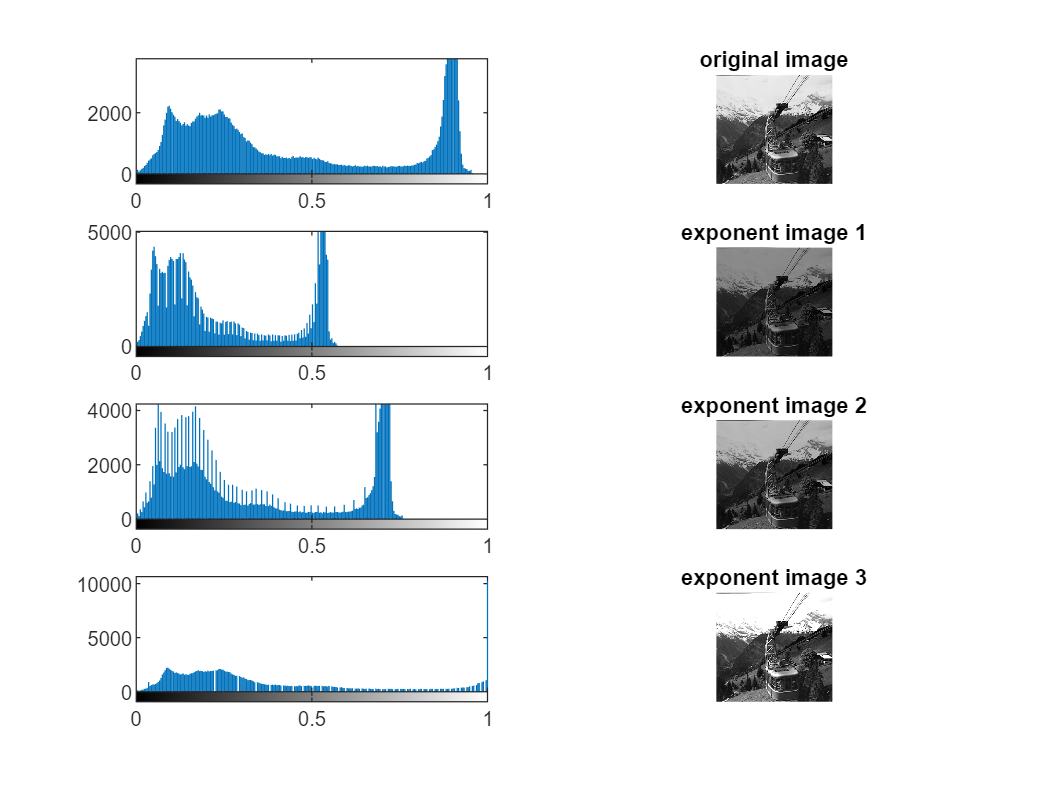

c=2;

out1=(c*(((1+0.3).^(id))-1));
out2=(c*(((1+0.4).^(id))-1));
out3=(c*(((1+0.6).^(id))-1));

subplot(4,2,1);imhist(id);
subplot(4,2,2);imshow(id);
title('original image');

subplot(4,2,3);imhist(out1);
subplot(4,2,4);imshow(out1);
title('exponent image 1');

subplot(4,2,5);imhist(out2);
subplot(4,2,6);imshow(out2);
title('exponent image 2');

subplot(4,2,7);imhist(out3);
subplot(4,2,8);imshow(out3);
title('exponent image 3');

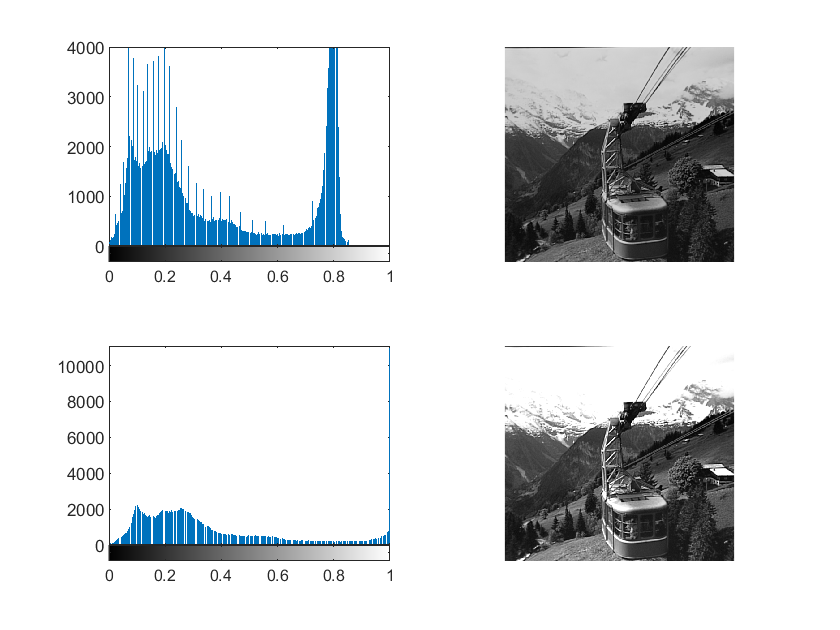

figure
out1=(3*(((1+0.3).^(id))-1));
out2=(4*(((1+0.3).^(id))-1));

subplot(2,2,1);imhist(out1);
subplot(2,2,2);imshow(out1);


subplot(2,2,3);imhist(out2);
subplot(2,2,4);imshow(out2);

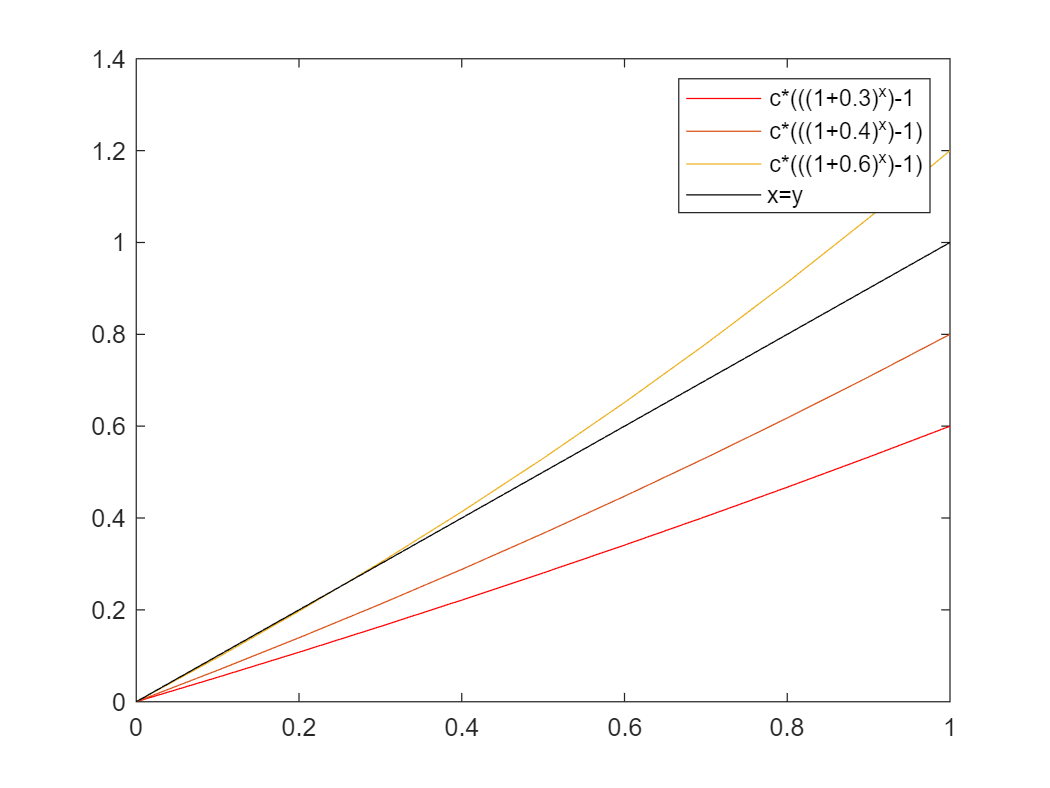



figure
plot(0:0.1:1,c*(((1+0.3).^(0:0.1:1))-1),'r');hold on
plot(0:0.1:1,c*(((1+0.4).^(0:0.1:1))-1));
plot(0:0.1:1,c*(((1+0.6).^(0:0.1:1))-1));
plot(0:0.1:1,0:0.1:1,'k');hold off
legend('c*(((1+0.3)^x)-1','c*(((1+0.4)^x)-1)','c*(((1+0.6)^x)-1)','x=y')

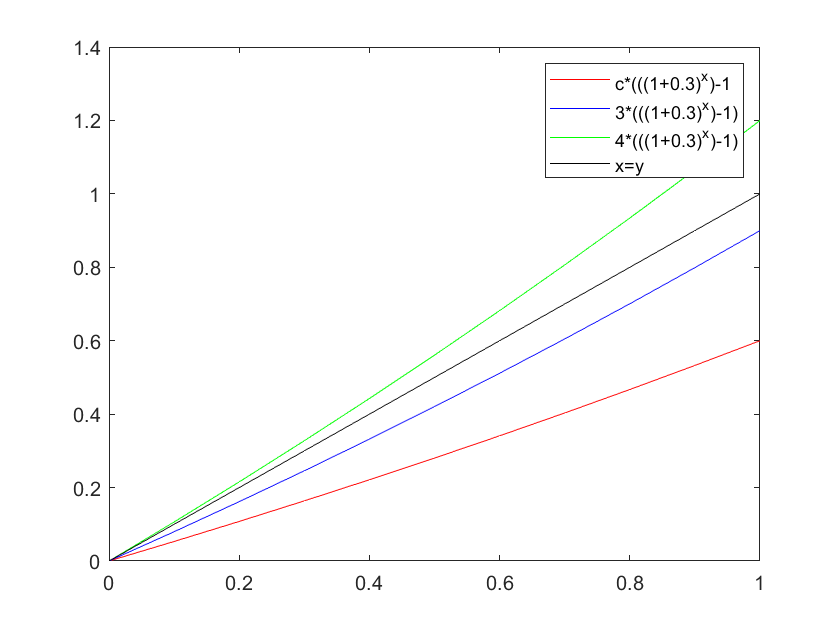

figure
plot(0:0.1:1,c*(((1+0.3).^(0:0.1:1))-1),'r');hold on
plot(0:0.1:1,3*(((1+0.3).^(0:0.1:1))-1),'b');
plot(0:0.1:1,4*(((1+0.3).^(0:0.1:1))-1),'g');
plot(0:0.1:1,0:0.1:1,'k');hold off
legend('c*(((1+0.3)^x)-1','3*(((1+0.3)^x)-1)','4*(((1+0.3)^x)-1)','x=y')

[m,n]=size(id);

c=2;
g=[0.5 0.7 0.9 1 2 3 4 5 6];
for r=1:length(g)
    for p=1:m
        for q=1:n
            img2(p,q)=c*id(p,q).^g(r);
        end
    end
    figure
    subplot(1,2,1);imhist(mat2gray(img2));title('img historgam');xlabel('gamma=');xlabel(g(r));
    subplot(1,2,2);imshow(img2);title('power-law transformation'); xlabel('gamma=');xlabel(g(r));
end

img2=imadjust(id,[0 1],[0 1],1/3);
figure 
subplot(2,2,1);imhist(id);
subplot(2,2,2);imshow(id);
title('original image');
subplot(2,2,3);imhist(img2);
subplot(2,2,4);imshow(img2);
title('output image');

img2=imadjust(id,[0 1],[1 0]);
figure
subplot(1,2,1);imhist(img2);
subplot(1,2,2);imshow(img2);
title('output image 2');

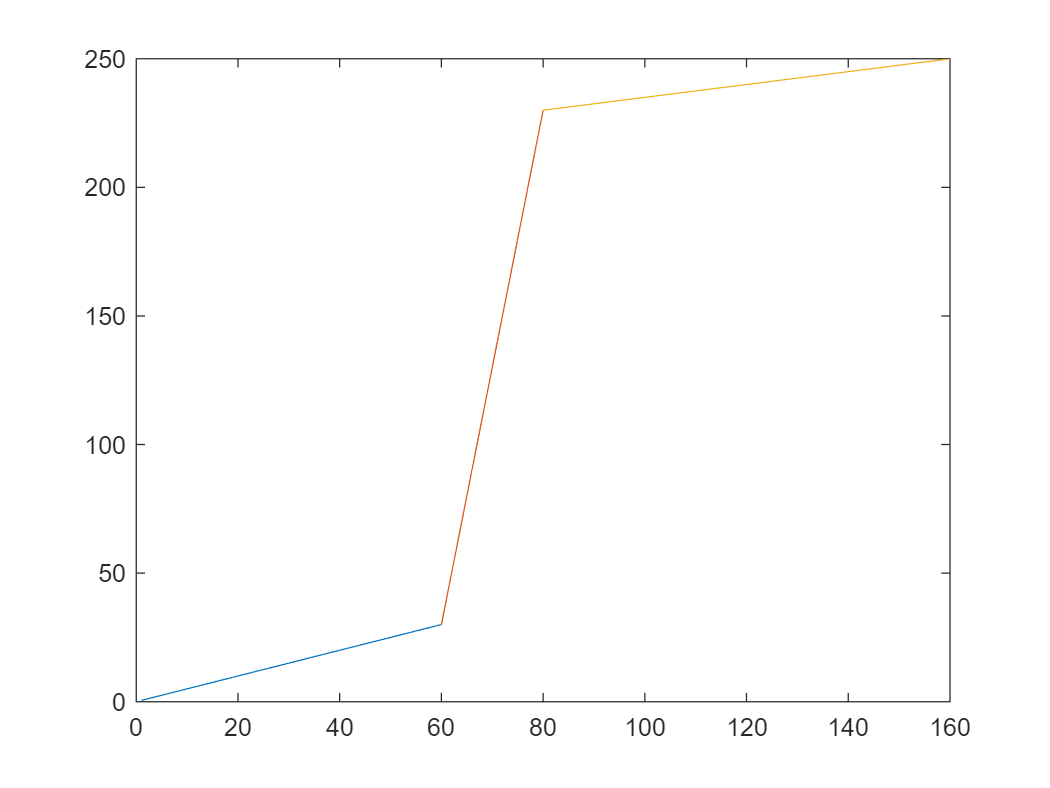

x=[20 20 20 20 20 20 20 40;160 60 60 60 60 60 60 40;160 60 70 70 70 70 60 40;160 60 70 80 80 70 60 40;160 60 70 80 80 70 60 40;160 60 70 70 70 70 60 40;160 60 60 60 60 60 60 60;160 120 120 120 120 120 120 120];
[m,n]=size(x);

for i=1:60
    lut(i)=0.5*i;
end
for i=60:80
    lut(i)=10*(i-57);
end
for i=80:160
    lut(i)=0.25*i+210;
end

for i=1:m
    for j=1:n
        y(i,j)=lut(x(i,j));
    end
end

t=1:60;
t1=60:80;
t2=80:160;
figure
plot(t,lut(t),t1,lut(t1),t2,lut(t2));

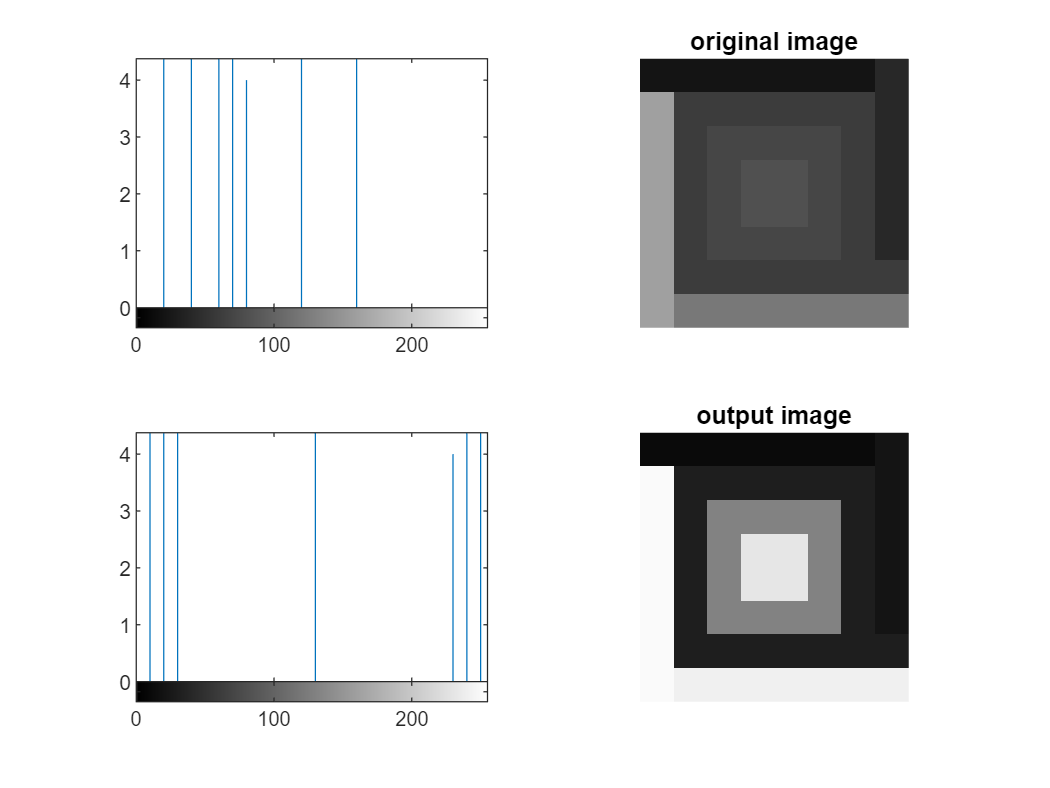

figure 
subplot(2,2,1);imhist(uint8(x),gray(256));
subplot(2,2,2);imshow(uint8(x),gray(256));
title('original image');
subplot(2,2,3);imhist(uint8(y),gray(256));
subplot(2,2,4);imshow(uint8(y),gray(256));
title('output image');

[m,n]=size(id);
for i=1:80
    lut(i)=i/4;
end
for i=80:120
    lut(i)=(180/40)*(i-80)+20;
end
for i=120:227
    lut(i)=(56/107)*(i-120)+200;
end

for i=1:m
    for j=1:n
        y(i,j)=lut(uint8(id(i,j)));
    end
end

Array indices must be positive integers or logical values.


figure 
subplot(2,2,1);imhist(uint8(id),gray(256));
subplot(2,2,2);imshow(uint8(id),gray(256));
title('original image');
subplot(2,2,3);imhist(uint8(y),gray(256));
subplot(2,2,4);imshow(uint8(y),gray(256));
title('output image');
